# **Model for parametric acoustic sources**

**2024-03-06**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

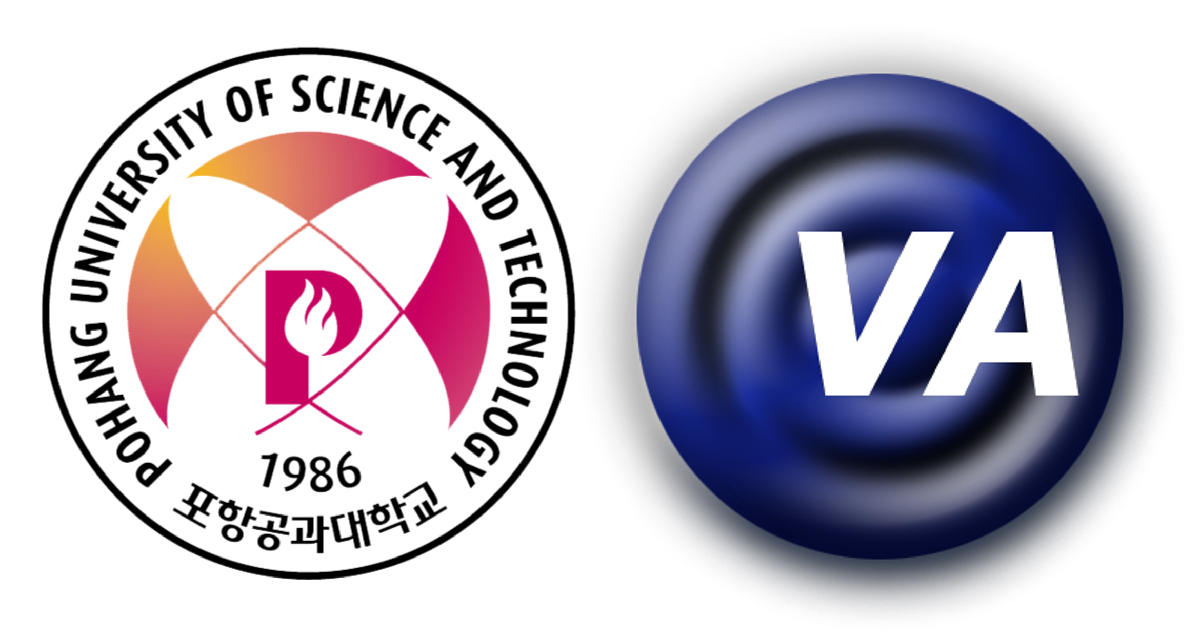

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

air.beta = 1.2;
air.rho = 1.21;
air.c   = 343;

P0 = 10;
R0 = 1.72;
f0 = 73.8e3;

Ralpha = 9.84;
alpha = 1/Ralpha;

r_ = logspace(-2,2,21);
f_ = 10e3;

For the first in the integrand, we desire a smooth function having the limits

 
$$\matrix{
1 & (r' \ll R_0 f_0 / f) \cr
-jf_0 R_0/f r' & (r' \gg R_0 f_0 / f)
}$$


and we choose


$$(1+j f r' / f_0 R_0)^{-1}$$


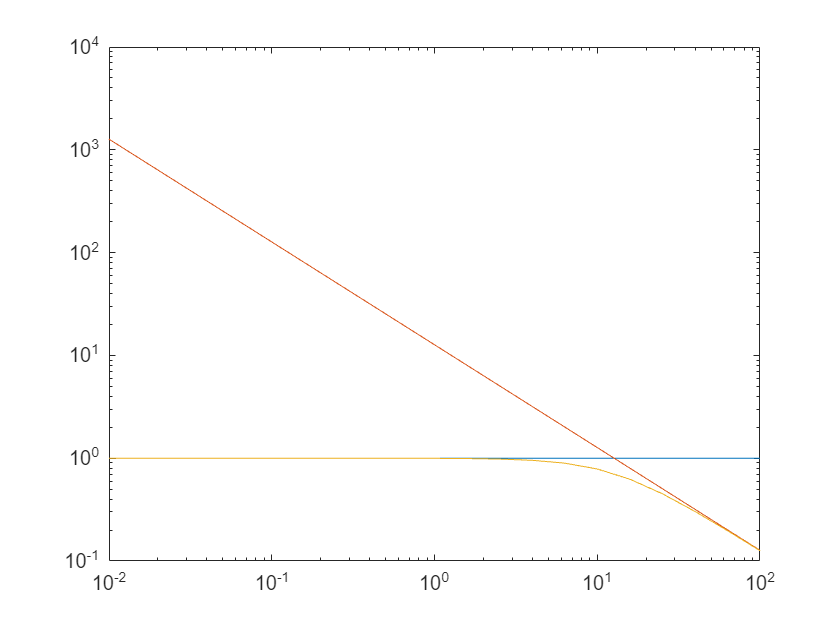

Sprd1 = ones(1,length(r_));
Sprd2 = @(f,r) -1j*f0*R0./(f*r);
SprdSmooth = @(f,r) (1+1j*f*r./(f0*R0)).^-1;

loglog(r_, Sprd1, ...
    r_, abs(Sprd2(f_,r_)), ...
    r_, abs(SprdSmooth(f_,r_)))


$$\chi = \frac{2 \pi \beta P_0 R_0 f_0}{\rho c^3} = \frac{X}{Y}$$


chi = 2*pi*air.beta*P0*R0*f0/(air.rho*air.c^3);


$$T^2(r') = \frac{2}{K^2} \left( \frac{1+K}{(1+2K)^{1/2}} - 1 \right) e^{- 2 \alpha r'$$


where $K \equiv 3 (\sigma/2\pi)^2$

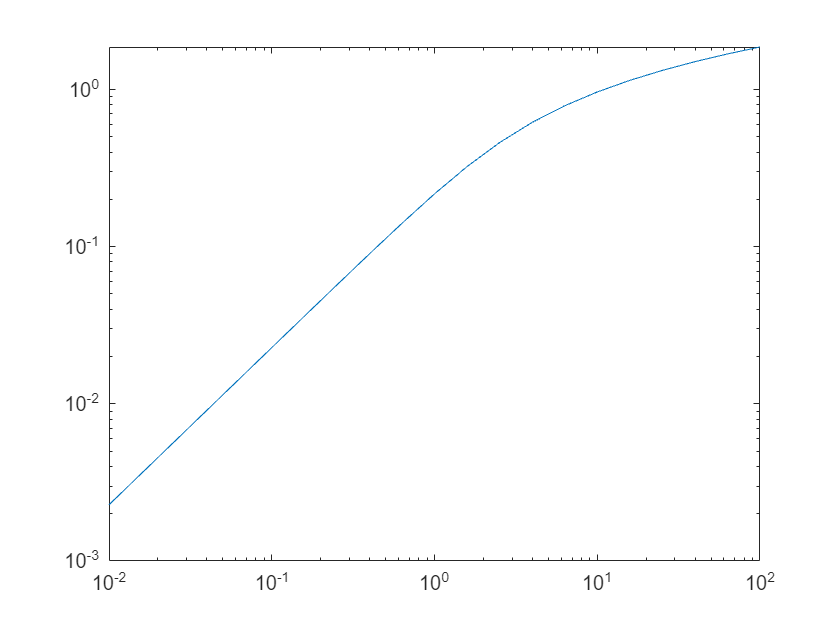

sigma_ = @(r) 2*chi*asinh(r./R0);
loglog(r_, sigma_(r_))

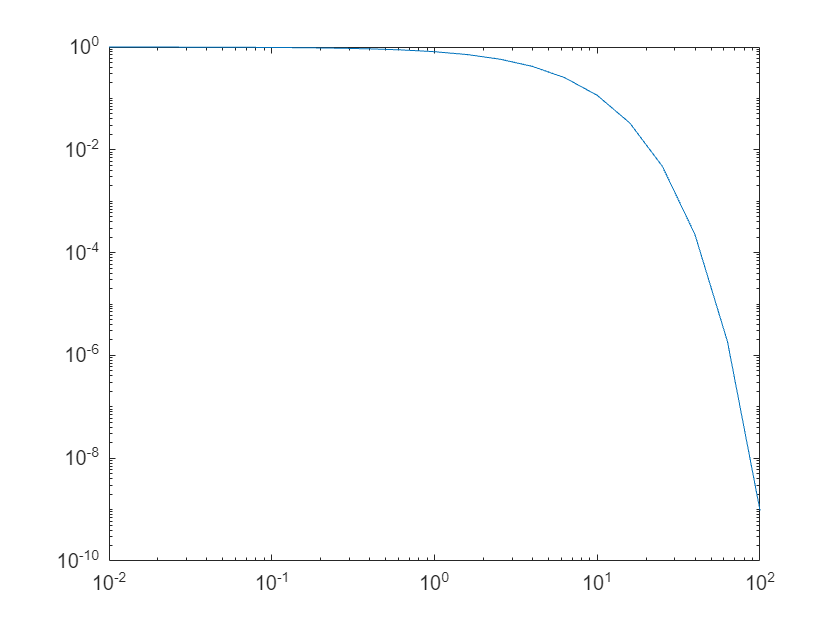


K_ = @(sigma) 3*(sigma./(2*pi)).^2;

Tsq_ = @(K, r) 2./K.^2.*((1+K)./sqrt(1+2*K)-1).*exp(-2*alpha.*r);
loglog(r_,Tsq_(K_(sigma_(r_)),r_))

2*alpha*R0*f0/f_

ans = 2.5800

g = integral(@(rr) chi/2*(f_/f0)^2*SprdSmooth(f_,rr).*Tsq_(K_(sigma_(rr)),rr)/R0, 1e-2, 1e2)

g = 0.0042 - 0.0012i

rObs = 1;
pObs = g*R0*P0/rObs;
20*log10(abs(pObs)/2e-5)

ans = 71.4146


G = 20*log10(abs(g))

G = -47.2754

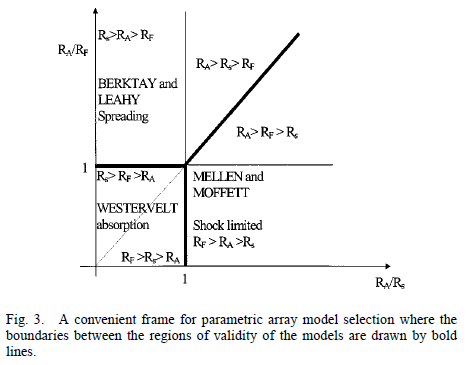

## Reference

- Kopp, L., et al. (2000). "Potential performance of parametric communications." IEEE Journal of Oceanic Engineering 25(3): 282-295.

###     Absorption limited model

- Westervelt, P. J. (1963). "Parametric Acoustic Array." The Journal of the Acoustical Society of America 35(4): 535-537.

###     Spreading limited Model

- Berktay, H. O. and D. J. Leahy (1974). "Farfield performance of parametric transmitters." The Journal of the Acoustical Society of America 55(3): 539-546.

###     Shock-wave limtied model

- Moffett, M. B. and R. H. Mellen (1977). "Model for parametric acoustic sources." The Journal of the Acoustical Society of America 61(2): 325-337.

## 3 basic distances which control the behavior of the parametric array

- Absorption length:                 $R_{A}=L_{a}=\frac{1}{\alpha_{p}\left(f_{p}\right)}$

- Rayleigh distnace:                 $R_{F}=z_{0}
=\frac{1}{2}ka^{2}
=\frac{\pi a^{2}}{\lambda_{p}}
=\frac{\pi a^{2}f_p}{c_{0}}$

- Shock formation distance:    $R_{S}=\bar{x}
=\frac{1}{\beta \varepsilon k_{p}}
=\frac{c_0}{2\pi \beta \varepsilon f_p}
=\frac{c_0^{2}}{2\pi \beta u_p f_p}$

## 3 basic modeling options

- Absorption limited

- Westervelt's initial model

- Design parameter:    $f_{p}$

- Spreading limited

- Berktay and Leahy

- Design parameter:    $f_{p}$, $a$

- Shock-wave limtied

- Mellen and Moffett

- Design parameter:    $f_{p}$, $a$, $u_{p}$

## Gol'dberg representation

- Gol'dberg number:                                                    $X=\Gamma=\frac{R_A}{R_S}=\frac{\beta \varepsilon k_{p}}{\alpha_p}
=\frac{2\pi \beta u_p f_p}{c_0^{2} \alpha \left(f_p \right)}$

- A properly normalized inverse Rayleigh distance:    $Y=\frac{R_A}{R_F}=\frac{\lambda_p}{\alpha_p \pi a^2}

=\frac{c_{0}}{\pi a^{2}f_p \alpha \left( f_p \right)}$

## KZK equation


$$\frac{\partial^2p}{\partial z \partial \tau}
- \frac{c_0}{2} \nabla_\perp^2 p
- \frac{\delta}{2 c_0^3} \frac{\partial^3 p}{\partial \tau^3}
=
\frac{\beta}{2 \rho_0c_0^3} \frac{\partial^2 p^2}{\partial \tau^2}$$


###     Assumption regarding the source

- The source is defined in the plane, $z=0$.

- The source has a characteristic radius, $a$.

- The source radiates at frequencies that satisfy the relation, $ka \gg 1$.

The last assumption ensures that the beam is reaonably directional.

Because of the assumed directionality of the beam, the sound is localized in the vincinty of the $z$ axis, and the wavefronts are quasi-planar.

###     High frequency limit on the parabolic approxiamation

It is necessary to consider the $\mathcal{O} \left( \varepsilon^2 \right)$ in $\nabla^2$.